clear;
clc;

global currentState cumulatedState historicCurrentState historicCumulatedState GDP numberOfRefugees totalDeaths listOfCountries GDPBetween useNonLinModel resultsDirectory dataDirectory plotsDirectory;

## Parameters

% Choose whether results are to be (re)calculated during run
% Setting to false may be useful e.g. in order to only plot results
calculateResults = true;

% true - nonlinear fitting method (nonlinear regression)
% false - logarithmic fitting method (linear regression)
useNonLinModel = false;

% Choose whether to plot results at the end
plotResults = true;

% Time span in which historic data about cumulated number of refugees are to be calculated.
% The only historic data show how many refugees came to each country each year.
% As model is based on total refugees currently present in the country,
% It is crucial to "sum up" number of refugees at least up to the year in which
% a fitting or simulation is started
cumulatingStartYear = 2000;
cumulatingEndYear = 2015;

% Time span in which to train a model
trainingStartYear = 2010;
trainingEndYear = 2014;

% Time span in which to simulate refugee movement
simulationStartYear = 2010;
simulationEndYear = 2016;

% Directories to load data from, to save results and results
dataDirectory = '../doc/data/';
resultsDirectory = '../doc/results/';
plotsDirectory = '../doc/plots/';

% starting vector used only for nonlinear regression
if useNonLinModel
    startingVector = [1e-3, 2, 0.8, 0.2];
end

## Main program

if calculateResults
    % Load all used datasets from files
    loadData();
    
    % Calculate historic data about number of refugees coming to countries each year
    % and cumulated number of refugees present in these countries in a certain year
    historicCumulatedState = calculateCumulatedNumberOfRefugeesFromYearToYear(cumulatingStartYear, cumulatingEndYear);
    historicCurrentState = getHistoricCurrentStateFromYearToYear(simulationStartYear, simulationEndYear);
    
    % Training model
    model = trainModel(trainingStartYear, trainingEndYear);
    
    % Getting leqarned coefficients from model
    v = model.Coefficients.Estimate;
    
    % Applying learned coefficients to simulate refugee movement
    [currentState, cumulatedState] =  simulateRefugeeMovement(v, simulationStartYear, simulationEndYear);
    
    % Saving historic and simulated data to files
    saveResults(currentState, 'current_state.csv');
    saveResults(historicCurrentState, 'historic_current_state.csv');
    saveResults(cumulatedState, 'cumulated_state.csv');
    saveResults(historicCumulatedState, 'historic_cumulated_state.csv');
    
    years = {currentState(:).Year};
    index = [years{:}] == 2015;
    
end

## Plotting

historicData = 24450

simulatedData = 19593

historicData = 36260

simulatedData = 25540

historicData = 370146

simulatedData = 129599

historicData = 832826

simulatedData = 762128

historicData = 1757547

simulatedData = 1771957

historicData = 2989613

simulatedData = 5089830

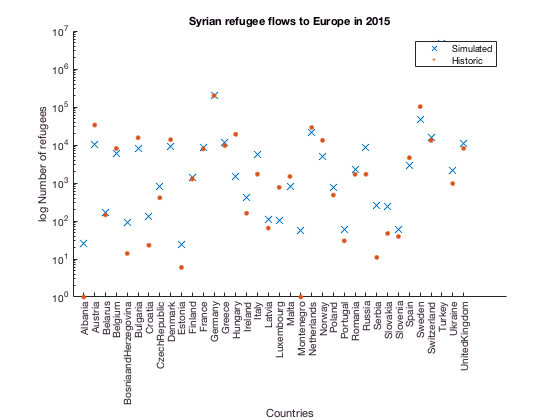

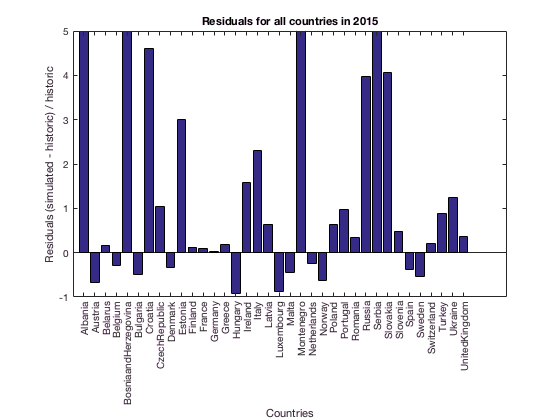

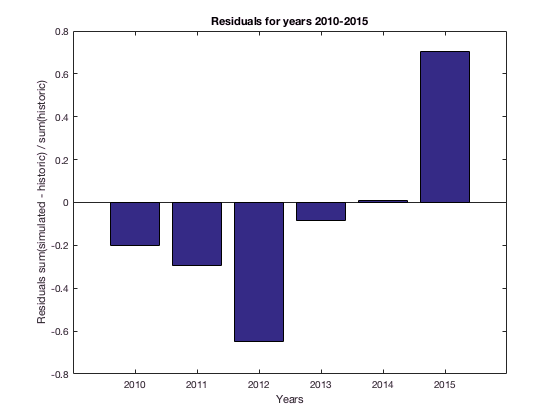

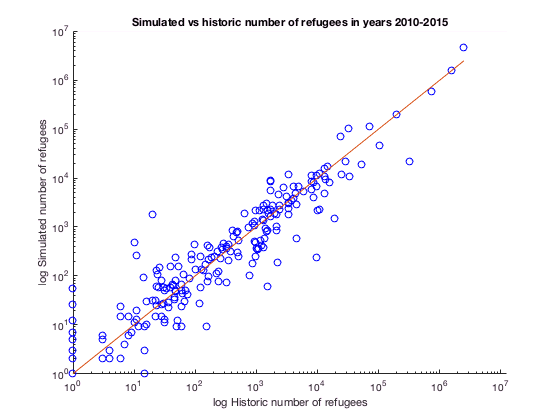

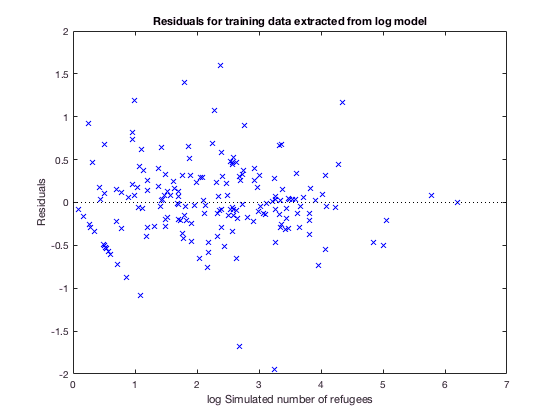

if plotResults
    close all;
%     plotHistoricAandSimulatedStateForCountriesFromYearToYear({'France', 'Sweden', 'Denmark'}, 2010, 2015);
    plotHistoricAandSimulatedStateForAllCountriesForYear(2015);
    plotResidualsForYear(2015);
    plotResidualsFromYearToYear(2010,2015);
    plotScatter(2010, 2015);
    plotResidualsForModel(model);
end

## Function to save resulting struct

% Inputs:
% data (struct) - data to be saved in file
% fileName (string) - name of the file (together with the extension) the data are to be saved in

function saveResults(data, fileName)
    global resultsDirectory;
    writetable(struct2table(data), [resultsDirectory fileName], 'Delimiter', ';')
end

## Functions to visualize data

% Function to plot both historic and simulated data about number of refugees coming in a certain year to a country
% Inputs:
% country (1x1 cell with string inside) - name of the country
% color (string) - color of the plot
function plotHistoricAandSimulatedStateForCountriesFromYearToYear(countries, startYear, endYear)
    global currentState historicCurrentState plotsDirectory;
    colors = {'magenta', 'cyan', 'red', 'green', 'blue', 'black'};
    years = {currentState(:).Year};
    legendLabels = {};
    titleLabel = {};
    fig = figure;
    for i = 1:length(countries)
        country = countries{i};
        color = colors{i};
        indexStart = find([years{:}] == startYear);
        indexEnd = find([years{:}] == endYear);
        plotCurrentY = [currentState(indexStart:indexEnd).(country)];
        plotHistoricY = [historicCurrentState(indexStart:indexEnd).(country)];
        plot(startYear:endYear, plotCurrentY, ':', 'Marker', 'x', 'MarkerSize', 10, 'Color', color);
        hold on;
        plot(startYear:endYear, plotHistoricY, 'Marker', '.', 'MarkerSize', 20, 'Color', color);
        legendLabels{end + 1} = [country ' simulated'];
        legendLabels{end + 1} = [country ' historic'];
        titleLabel{end + 1} = [' ' country];
    end
    
    hold off;
    axes = gca;
    axes.XTick = startYear:endYear;
    title(['Current number of refugees coming to' titleLabel]);
    xlabel('Years');
    ylabel('Number of refugees');
    legend(legendLabels);
    
    saveas(fig, [plotsDirectory 'current_state_for_all_years.jpg']); 
end

function plotHistoricAandSimulatedStateForAllCountriesForYear(year)
    global currentState historicCurrentState plotsDirectory;
    
    deletedFields = {'Year'};
    countries = fieldnames(rmfield(currentState, deletedFields));
    
    years = {currentState(:).Year};
    
    index = [years{:}] == year;
    plotCurrentY = struct2cell(rmfield(currentState(index), deletedFields));
    plotHistoricCurrentY = struct2cell(rmfield(historicCurrentState(index), deletedFields));
    
    fig = figure;
    scatter(1:length(countries), [plotCurrentY{:}], 50, 'Marker', 'x');
    hold on;
    scatter(1:length(countries), [plotHistoricCurrentY{:}], 200, 'Marker', '.');
    hold off;
    
    axes = gca;
    axes.XTick = 1:length(countries);
    axes.XTickLabel = countries;
    axes.XTickLabelRotation = 90;
    axes.YScale = 'log';
    title(['Syrian refugee flows to Europe in ' num2str(year)]);
    xlabel('Countries');
    ylabel('log Number of refugees');
    legend('Simulated', 'Historic');
    
    saveas(fig, [plotsDirectory 'current_state_for_one_year.jpg']); 
end

% Function to plot scatter with relation between historic and simulated number of refugees coming in all trained and simulated years
function plotScatter(startYear, endYear)
    global historicCurrentState currentState plotsDirectory;
    
    deletedFields = {'Year'};
    years = {currentState(:).Year};
    
    fig = figure;
    allX = [];
    allY = [];
    for year = startYear:endYear
        index = [years{:}] == year;
        plotHistoricCurrentY = struct2cell(rmfield(historicCurrentState(index), deletedFields));
        allX = horzcat(allX, [plotHistoricCurrentY{:}]);
        plotCurrentY = struct2cell(rmfield(currentState(index), deletedFields));
        allY = horzcat(allY, [plotCurrentY{:}]);
    end
    
    scatter(allX, allY, 50, 'blue');
    hold on;
    plot(allX,allX);
    hold off;
    axes = gca;
    axes.XScale = 'log';
    axes.YScale = 'log';
    title(['Simulated vs historic number of refugees in years ' num2str(startYear) '-' num2str(endYear)]);
    xlabel('log Historic number of refugees');
    ylabel('log Simulated number of refugees');
    axis equal;
    
    saveas(fig, [plotsDirectory 'scatter_plot.jpg']); 
end

function plotResidualsForYear(year)
    global currentState historicCurrentState plotsDirectory;
    
    deletedFields = {'Year'};
    countries = fieldnames(rmfield(currentState, deletedFields));
    
    years = {currentState(:).Year};
    
    index = [years{:}] == year;
    plotCurrentY = struct2cell(rmfield(currentState(index), deletedFields));
    plotCurrentY = [plotCurrentY{:}];
    plotHistoricCurrentY = struct2cell(rmfield(historicCurrentState(index), deletedFields));
    plotHistoricCurrentY = [plotHistoricCurrentY{:}];
    
    residuals = (plotCurrentY - plotHistoricCurrentY) ./ plotHistoricCurrentY;
    
    fig = figure;
    bar(1:length(countries), residuals);
    
    axes = gca;
    axes.XTick = 1:length(countries);
    axes.XTickLabel = countries;
    axes.XTickLabelRotation = 90;
    axes.YLim = [-1 5];
    title(['Residuals for all countries in ' num2str(year)]);
    xlabel('Countries');
    ylabel('Residuals (simulated - historic) / historic');
    
    saveas(fig, [plotsDirectory 'residuals_for_one_year.jpg']); 
end

function plotResidualsFromYearToYear(startYear, endYear)
    global historicCurrentState currentState plotsDirectory;
    
    deletedFields = {'Year'};
    years = {currentState(:).Year};
    
    fig = figure;
    i = 0;
    for year = startYear:endYear
        i = i + 1;
        index = [years{:}] == year;
        plotCurrentY = struct2cell(rmfield(currentState(index), deletedFields));
        plotCurrentY = [plotCurrentY{:}];
        plotHistoricCurrentY = struct2cell(rmfield(historicCurrentState(index), deletedFields));
        plotHistoricCurrentY = [plotHistoricCurrentY{:}];
        residuals(i) = sum(plotCurrentY - plotHistoricCurrentY) / sum(plotHistoricCurrentY);
        historicData = sum(plotHistoricCurrentY)
        simulatedData = sum(plotCurrentY)
    end
    
    bar(1:i, residuals);
    axes = gca;
    axes.XTickLabel = startYear:endYear;
    title(['Residuals for years ' num2str(startYear) '-' num2str(endYear)]);
    xlabel('Years');
    ylabel('Residuals sum(simulated - historic) / sum(historic)');
    
    saveas(fig, [plotsDirectory 'residuals_for_all_years.jpg']); 
end

function plotResidualsForModel(model)
    global plotsDirectory;
    fig = figure;
    plotResiduals(model, 'fitted');
    xlabel('log Simulated number of refugees');
    title('Residuals for training data extracted from log model');
    
    saveas(fig, [plotsDirectory 'model_residuals.jpg']); 
end

## Simulation functions

% Fynction to calculate simulated number of refugees
% Inputs:
% b (vector 1x4 or 1x5 depending on the used fitting method) - vector of coefficients learned in the function trainModel
% x (vector 1x4) - vector of input data in the form [total_deaths, GDP_of_country, GDP_between, previous_number_of_refugees]
% Output:
% result (number) - simulated number of refugees for given input data (for a given country in a given year)
function result = calculateNumberOfRefugees(b, x)
    global useNonLinModel;
    if useNonLinModel
        result = b(1).*x(:,1).*x(:,2).^b(2)./(x(:,3).^b(3).*x(:,4).^b(4));
    else
        result = 10^b(1) * x(:,1)^b(2) * x(:,2)^b(3) * x(:,3)^b(4) * x(:,4)^b(5);
    end
end

% Function to train the model
% Inputs:
% startYear (number) - first year of training period
% endYear (number) - last year of training period
% Output:
% model - trained model with information about fitting accuracy
function model = trainModel(startYear, endYear)
    
    global listOfCountries useNonLinModel startingVector;
    
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    for i = 1:numberOfYears
        year = listOfYears(i);
        
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            
            total_deaths = getTotalDeathsInSyriaInYear(year - 1);
%             total_deaths = getTotalCumulatedDeathsInSyriaInYear(year - 1);
            GDP_of_country = getGDPOfCountryInYear(country, year - 1);
            GDP_between = getGDPBetweenOfCountryInYear(country, year - 1);
            previous_number_of_refugees = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year-1);
            
            historic_number_of_refugees = getHistoricNumberOfRefugeesInCountryInYear(country, year);
            
            row_index = (i-1)*numberOfCountries+j;
            
            if useNonLinModel
                X(row_index, 1:4) = [total_deaths, GDP_of_country, GDP_between, previous_number_of_refugees];
                y(row_index, 1) = historic_number_of_refugees;
            else
                X(row_index, 1:4) = log10([total_deaths, GDP_of_country, GDP_between, previous_number_of_refugees]);
                y(row_index, 1) = log10(historic_number_of_refugees);
            end
        end
    
    end
    
    if useNonLinModel
        model = fitnlm(X, y, @calculateNumberOfRefugees, startingVector);
    else
        model = fitlm(X, y);
    end
    
end

% Function to simulate number of people coming to a certain country in the given time span
% Inputs:
% v (vector 1x4 or 1x5 depending on the used fitting method) - vector of coefficients learned in the function trainModel
% startYear (number) - first year of simulation period
% endYear (number) - last year of simulation period
% Output:
% currentState (struct) - sctructure containing simulated number of people coming to certain countries in time from startYear to endYear
% cumulatedState (struct) - structure containing simulated number of people actually present in certain countries in time from startYear to endYear
function [currentState, cumulatedState] =  simulateRefugeeMovement(v, startYear, endYear)
    
    global listOfCountries;
    
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    fields = ['Year'; listOfCountries];
    currentState = num2cell(zeros(1,numberOfCountries+1));
    currentState = cell2struct(currentState, fields, 2);
    
    cumulatedState = currentState;
    
    for i = 1:numberOfYears
        
        year = listOfYears(i);
        currentState(i).Year = year;
        cumulatedState(i).Year = year;
        
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            
            total_deaths = getTotalDeathsInSyriaInYear(year - 1);
%             total_deaths = getTotalCumulatedDeathsInSyriaInYear(year - 1);
            GDP_of_country = getGDPOfCountryInYear(country, year - 1);
            GDP_between = getGDPBetweenOfCountryInYear(country, year - 1);
            
            % During first iteration take historic data about cumulated number of refugees
            % In next steps take value calculated in a previous iteration
            previous_number_of_refugees = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year-1);
%             if i < 2
%                 previous_number_of_refugees = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year-1);
%             else
%                 previous_number_of_refugees = cumulatedState(i-1).(country{1});
%                 previous_number_of_refugees = getCumulatedNumberOfRefugeesInCountryInYear(country, year-1);
%             end
            
            x = [total_deaths, GDP_of_country, GDP_between, previous_number_of_refugees];
            calculatedNumberOfRefugees = calculateNumberOfRefugees(v, x);
            calculatedNumberOfRefugees = floor(calculatedNumberOfRefugees);
            
            currentState(i).(country{1}) = calculatedNumberOfRefugees;
            if i < 2
                cumulatedState(i).(country{1}) = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year-1) + calculatedNumberOfRefugees;
            else
                cumulatedState(i).(country{1}) = cumulatedState(i-1).(country{1}) + calculatedNumberOfRefugees;
            end
            
        end

    end
    
end

## Functions to get needed data from available datasets

% Function returning total number of refugees leaving Syria in a certain year
% Input:
% year (number) - year for which to calculate the number
% Output:
% result (number) - total number of refugees leaving Syria in year
function result = getTotalNumberOfRefugeesInYear(year)
    global numberOfRefugees;
    index = strcmp({numberOfRefugees.Year}, string(year))==1;
    
    if sum(index) > 0
        a = {numberOfRefugees(index).Count};
        if ~isempty(a)
            m = str2double(a);
            result = sum(m);
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getHistoricCurrentStateFromYearToYear(startYear, endYear)
    
    global listOfCountries;
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    historicCurrentState = num2cell(zeros(1,numberOfCountries));
    historicCurrentState = [startYear, historicCurrentState];
    fields = ['Year'; listOfCountries];
    historicCurrentState = cell2struct(historicCurrentState, fields, 2);
    
    for i = 1:numberOfYears
        year = listOfYears(i);
        historicCurrentState(i).Year = year;
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            historicCurrentState(i).(country{1}) = getHistoricNumberOfRefugeesInCountryInYear(country, year);
        end
    end
    
    result = historicCurrentState;
end

function result = getHistoricNumberOfRefugeesInCountryInYear(country, year)
    global numberOfRefugees;
    index = strcmp({numberOfRefugees.Year}, string(year))==1 & strcmp({numberOfRefugees.Country}, country)==1;
    
    if sum(index) > 0
        a = str2double(numberOfRefugees(index).Count);
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getTotalCumulatedDeathsInSyriaInYear(year)
    global totalDeaths;
    index = find(strcmp({totalDeaths.Year}, string(year))==1);
    
    if sum(index) > 0
        a = 0;
        for i = index:-1:1
            a = a + str2double(totalDeaths(i).Count);
        end
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getTotalDeathsInSyriaInYear(year)
    global totalDeaths;
    index = strcmp({totalDeaths.Year}, string(year))==1;
    
    if sum(index) > 0
        a = str2double(totalDeaths(index).Count);
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getGDPOfCountryInYear(country, year)
    global GDP;
    index = strcmp({GDP.Year}, string(year))==1;
    if sum(index) > 0
        a = str2double(GDP(index).(country{1}));
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getGDPBetweenOfCountryInYear(country, year)
    global GDPBetween;
    index = strcmp({GDPBetween.Year}, string(year))==1;
    
    if sum(index) > 0
        a = str2double(GDPBetween(index).(country{1}));
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = calculateCumulatedNumberOfRefugeesFromYearToYear(startYear, endYear)
    
    global listOfCountries;
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    cumulatedState = num2cell(zeros(1,numberOfCountries));
    cumulatedState = [startYear, cumulatedState];
    fields = ['Year'; listOfCountries];
    cumulatedState = cell2struct(cumulatedState, fields, 2);
    
    for i = 1:numberOfYears
        year = listOfYears(i);
        cumulatedState(i).Year = year;
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            if i < 2
                cumulatedState(i).(country{1}) = getHistoricNumberOfRefugeesInCountryInYear(country, year);
            else
                cumulatedState(i).(country{1}) = cumulatedState(i-1).(country{1}) + getHistoricNumberOfRefugeesInCountryInYear(country, year);
            end
        end
    end
    
    result = cumulatedState;
end

function result = getCumulatedNumberOfRefugeesInCountryInYear(country, year)
    
    global cumulatedState;
    a = {cumulatedState.Year};
    index = find([a{:}] == year);
    
    if ~isempty(index)
        number = cumulatedState(index).(country{1});
        if number > 0
            result = number;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year)
    
    global historicCumulatedState;
    a = {historicCumulatedState.Year};
    index = find([a{:}] == year);
    
    if ~isempty(index)
        number = historicCumulatedState(index).(country{1});
        if number > 0
            result = number;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getCurrentNumberOfRefugeesInCountryInYear(country, year)
    
    global currentState;
    a = {currentState.Year};
    index = find([a{:}] == year);
    
    if ~isempty(index)
        number = currentState(index).(country{1});
        if number > 0
            result = number;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getHistoricCurrentNumberOfRefugeesInCountryInYear(country, year)
    
    global historicCurrentState;
    a = {historicCurrentState.Year};
    index = find([a{:}] == year);
    
    if ~isempty(index)
        number = historicCurrentState(index).(country{1});
        if number > 0
            result = number;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

## Loading all needed datasets

function loadData()
    
    global GDP numberOfRefugees totalDeaths GDPBetween listOfCountries;
    
    fileName = 'GDP_Europe_2010-2016.csv';
    GDP = importDataFile(fileName, ';');
    
    fileName = 'Syrian_Refugees_1980-2015_toEU.csv';
    numberOfRefugees = importDataFile(fileName, ';');
    
    fileName = 'Total_deaths_Syria_2008-2015.csv';
    totalDeaths = importDataFile(fileName, ';');
    
    fileName = 'gdp_between.csv';
    GDPBetween = importDataFile(fileName, ';');
    
    GDPfields = fieldnames(GDP);
    GDBBetweenFields = fieldnames(GDPBetween);
    
    GDPListOfCountries = unique(GDPfields(2:end)); % remove 'Year' field
    GDPBetweenListOfCountries = unique(GDBBetweenFields(2:end));
    DataListOfCountries = unique({numberOfRefugees(:).Country});
    
    listOfCountries = intersect(GDPListOfCountries, GDPBetweenListOfCountries);
    listOfCountries = intersect(listOfCountries, DataListOfCountries);
    
%     index = strcmp(listOfCountries, 'Turkey');
%     listOfCountries(index) = [];
%     index = strcmp(listOfCountries, 'Russia');
%     listOfCountries(index) = [];
    
    GDPMissingCountries = setdiff(GDPListOfCountries, listOfCountries);
    GDP = rmfield(GDP, GDPMissingCountries);
    
    GDPBetweenMissingCountries = setdiff(GDPBetweenListOfCountries, listOfCountries);
    GDPBetween = rmfield(GDPBetween, GDPBetweenMissingCountries);
    
    % Sorting countries alphabetically
    fields = ['Year'; listOfCountries];
    GDP = orderfields(GDP, fields);
    GDPBetween = orderfields(GDPBetween, fields);
    
end

## Importing data from one file

function dataStruct = importDataFile(fileName, delimiter)
    
    global dataDirectory;
    filePath = strcat(dataDirectory, fileName);
    fileID = fopen(filePath);
    tline = fgetl(fileID);
    nColumns = length(find(tline==delimiter))+1;
    
    frewind(fileID);
    
    field = textscan(fileID, repmat('%s', 1, nColumns), 1, 'Delimiter', delimiter);
    field = horzcat(field{:});
    value = textscan(fileID, repmat('%s', 1, nColumns), 'Delimiter', delimiter);
    value = horzcat(value{:});
    
    dataStruct = cell2struct(value, field, 2);

end